Load and prepare the training data

load('C:\Users\camsc\Documents\projects\cube_solver\data_files\scramble_dataset_1_to_15_init_0_50000.mat', 'cubeStateSequences', 'scrambles');

encodedScrambles = data.conversion.convertMovesToOneHot(scrambles);
oneHotCubeStateSequences = data.conversion.convertCubeStateSequencesToOneHot(cubeStateSequences);

Initialize the network to be trained

config = struct;
config.lstmWidth = 6;
network = net.initCubeStatePredictorLstm(config);

Train the network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:20        0.005         0.32489
           50       50       00:14:46        0.005         0.27819
          100      100       00:29:26        0.005         0.27409
          150      150       00:44:10        0.005         0.27388
          200      200       00:58:59        0.005         0.27379
Training stopped: Stopped manually


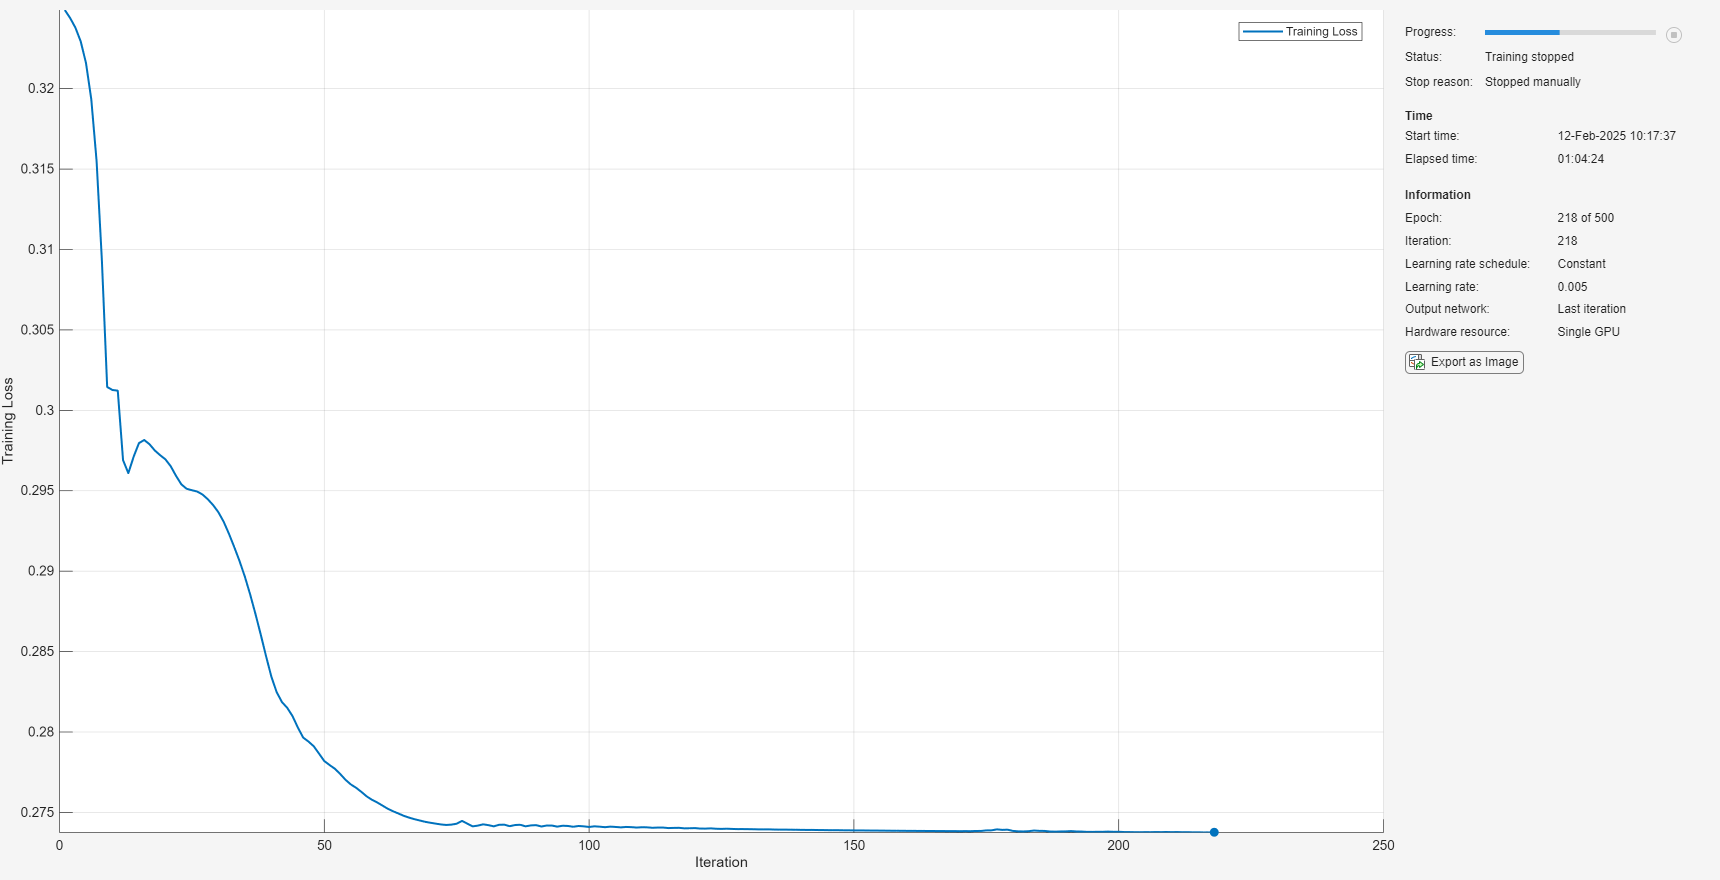

opts = trainingOptions('adam', ...
    'Plots', 'training-progress', ...
    'InitialLearnRate', 0.005, ...
    'MiniBatchSize', 50000, ...
    'MaxEpochs', 500);
opts.TargetDataFormats = 'CSBT';
% opts.Shuffle = 'every-epoch';

trainedNetwork = trainnet(encodedScrambles, oneHotCubeStateSequences, network, 'binary-crossentropy', opts);

Show some predictions

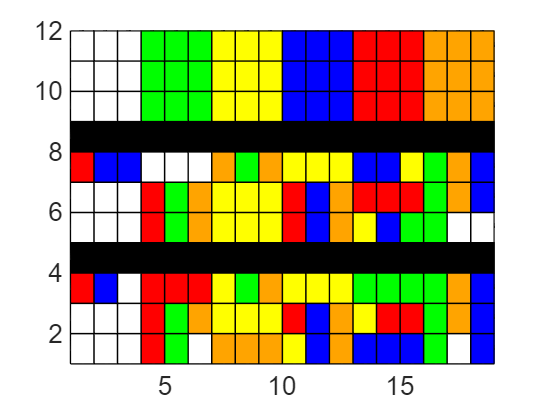

encodedScramble = encodedScrambles{1};
scramble = scrambles{1};
predictedCubeStates = predict(trainedNetwork6, encodedScramble);
predictedRawFaces = data.conversion.convertOneHotSequencesToCubeStates({predictedCubeStates});

stateSequencePrediction = predictedRawFaces{1};
numMoves = numel(scramble);

predictedCube = Cube;
correctCube = Cube;
for moveNum = 1:numMoves
    correctCube.rotate(scramble(moveNum));
    predictedCube.setStateFromRawFaces(stateSequencePrediction(:, :, :, 1, moveNum));
    correctCube.show2dComparison(predictedCube);
end